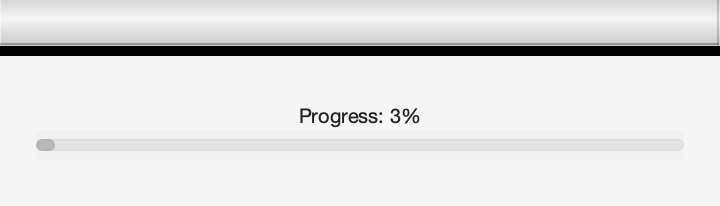

------ ELBO increased by: 300710.1828
------ ELBO increased by: 20255.9114
------ ELBO increased by: 12330.3608
------ ELBO increased by: 8429.0817
------ ELBO increased by: 5905.0436
------ ELBO increased by: 2965.2320
------ ELBO increased by: 1424.1945
------ ELBO increased by: 795.5485
Removed 2 factors in iteration 89
Removed 2 factors in iteration 90
------ ELBO increased by: 1811.4398
Removed 2 factors in iteration 91
Removed 2 factors in iteration 92
Removed 8 factors in iteration 97
Removed 6 factors in iteration 98
Removed 2 factors in iteration 99
Removed 2 factors in iteration 100
------ ELBO increased by: 7672.8700
Removed 3 factors in iteration 101
Removed 1 factor in iteration 103
Removed 1 factor in iteration 105
Removed 2 factors in iteration 107
Removed 1 factor in iteration 109
------ ELBO increased by: 2828.2299
------ ELBO increased by: 99.6500
------ ELBO increased by: 79.1476
------ ELBO increased by: 65.0046
------ ELBO increased by: 55.9181
------ ELBO increase


Progress:   1%


------ ELBO increased by: 300710.3507
------ ELBO increased by: 20242.1849
------ ELBO increased by: 12378.8380
------ ELBO increased by: 8320.1825
------ ELBO increased by: 5815.5561
------ ELBO increased by: 3241.6193
------ ELBO increased by: 1473.3231
------ ELBO increased by: 668.3256
Removed 2 factors in iteration 89
Removed 1 factor in iteration 90
------ ELBO increased by: 1402.3693
Removed 1 factor in iteration 91
Removed 1 factor in iteration 93
Removed 1 factor in iteration 94
Removed 3 factors in iteration 95
Removed 1 factor in iteration 96
Removed 2 factors in iteration 97
Removed 3 factors in iteration 98
Removed 4 factors in iteration 99
Removed 1 factor in iteration 100
------ ELBO increased by: 6018.9701
Removed 1 factor in iteration 101
Removed 2 factors in iteration 102
Removed 2 factors in iteration 106
Removed 1 factor in iteration 107
------ ELBO increased by: 2209.2600
------ ELBO increased by: 116.3888
------ ELBO increased by: 77.3813
------ ELBO increased by:


Progress:   2%


------ ELBO increased by: 300712.5632
------ ELBO increased by: 19953.7080
------ ELBO increased by: 12724.4973
------ ELBO increased by: 8577.2377
------ ELBO increased by: 6020.1924
------ ELBO increased by: 2664.1095
------ ELBO increased by: 1262.0030
------ ELBO increased by: 823.5953
Removed 2 factors in iteration 88
Removed 2 factors in iteration 89
Removed 2 factors in iteration 90
------ ELBO increased by: 2473.8349
Removed 2 factors in iteration 91
Removed 1 factor in iteration 93
Removed 6 factors in iteration 94
Removed 1 factor in iteration 96
Removed 4 factors in iteration 100
------ ELBO increased by: 4967.9551
Removed 1 factor in iteration 101
Removed 7 factors in iteration 102
Removed 1 factor in iteration 103
Removed 1 factor in iteration 104
------ ELBO increased by: 3516.5082
------ ELBO increased by: 96.1582
------ ELBO increased by: 76.0313
------ ELBO increased by: 66.4740
------ ELBO increased by: 70.5648
------ ELBO increased by: 57.3859
------ ELBO increased b


Progress:   3%


------ ELBO increased by: 300709.7976
------ ELBO increased by: 20732.5378
------ ELBO increased by: 11812.4987
------ ELBO increased by: 8144.9350
------ ELBO increased by: 5515.9437
------ ELBO increased by: 3299.5454
------ ELBO increased by: 1701.5752
------ ELBO increased by: 702.2271
Removed 1 factor in iteration 84
Removed 1 factor in iteration 90
------ ELBO increased by: 1099.0436
Removed 1 factor in iteration 91
Removed 1 factor in iteration 92
Removed 1 factor in iteration 94
Removed 1 factor in iteration 95
Removed 1 factor in iteration 97
Removed 3 factors in iteration 98
Removed 1 factor in iteration 99
Removed 4 factors in iteration 100
------ ELBO increased by: 4709.3798
Removed 4 factors in iteration 101
Removed 1 factor in iteration 102
Removed 1 factor in iteration 103
Removed 5 factors in iteration 104
Removed 1 factor in iteration 105
Removed 1 factor in iteration 106
Removed 2 factors in iteration 108
Removed 1 factor in iteration 109
Removed 1 factor in iteration

% Clear the workspace
close all; clearvars; clc;

rc = RunConfig.getInstance();
rc.inputValidation = true;
rc.enableLogging = true;

% Logging
logFileName = ['logs/', mfilename, '.txt'];
if ~exist('logs', 'dir')
    mkdir('logs');
end

% diary(logFileName); % start logging

% Start timing
tic;

% Setup
numOfFolds = 10;
numModelSelectionRuns = 10;
K = 100;
baseDir = 'datasets/hermes/';

% Progress bar
numRuns = numOfFolds * numModelSelectionRuns;
h = waitbar(0, 'Progress...');

res = Results(numOfFolds); % obj

% [NOTE] For prediction tasks, list input views before output views.
viewFilenames = {
    'rs_fMRI_ALFF.csv', ...
    'rs_fMRI_REHO.csv', ...
    'demographics.csv', ...
    'MRS.csv', ...
    'clinical.csv', ... 
    'cognitive.csv', ...
    'sMRI.csv', ...
    'nutrition.csv', ...
    'microbiome.csv', ...
    'classification.csv'
};

% [NOTE] For now this is always set to 1!
outputViewsCnt = 1;

% Initialize cell array to hold the data and read each file
views = cell(size(viewFilenames));
M = numel(views);
for m = 1:M
    filePath = fullfile(baseDir, viewFilenames{m});
    views{m} = readmatrix(filePath, 'FileType', 'text')'; % TODO: set `featuresInCols` property
end

% Labels
y = views{end};

% cv = cvpartition(y, 'KFold', numOfFolds);

totalVars = nan(1, numOfFolds);
factorsVars = nan(1, numOfFolds);
varsWithin = cell(1, numOfFolds);
relVarsWithin = cell(1, numOfFolds);
factors = {};
Ks = {};
elbos = {};
Ws = {};
taus = {};

for foldIdx = 1:numOfFolds
    % Get training and testing indices
    % trainIdx = cv.training(foldIdx);
    % testIdx = cv.test(foldIdx);

    % Import train and test indices
    filePath = fullfile(baseDir, sprintf('FoldsIdx/fold_%d', foldIdx - 1), 'train.csv');
    trainIdx = readmatrix(filePath, 'FileType', 'text');

    filePath = fullfile(baseDir, sprintf('FoldsIdx/fold_%d', foldIdx - 1), 'test.csv');
    testIdx = readmatrix(filePath, 'FileType', 'text');

    trainViews = cell(size(views));

    for v = 1:numel(views)
        trainViewData = views{v}(:, trainIdx);
        scaler = StandardScaler();

        scaler = scaler.fit(trainViewData);

        % Don't scale the last view
        if v ~= M
            trainViews{v} = scaler.transform(trainViewData);
            views{v} = scaler.transform(views{v});
        else 
            trainViews{v} = trainViewData;
        end
    end

    bestModel = NaN;
    bestElbo = -inf;
    bestIter = 0;

    for s = 1:numModelSelectionRuns
        % model = BGFA(trainViews, M - 1, K, 'B', 10000, 1e-4); % Views are
        % expected in DxN format
        model = SGFA(trainViews, K, 10000, 1e-4); % Views are expected in DxN format
        [elboVals, iter] = model.fit(10);

        if elboVals(end) > bestElbo
            bestModel = model;
            bestElbo = elboVals(end);
            bestIter = iter;
        end
        % Progress bar
        k = (foldIdx - 1) * numModelSelectionRuns + s;
        waitbar(k/numRuns, h, sprintf('Progress: %d%%', round(100 * k/numRuns)));
        fprintf('\rProgress: %3.0f%%\n', 100 * k/numRuns);
    end

    [K_eff, predictionsTest] = bestModel.makePredictions(views, trainIdx, testIdx);

    % Compute variances
    totalVars(foldIdx) = bestModel.totalVar;
    factorsVars(foldIdx) = bestModel.factorsVar;
    varsWithin{foldIdx} = bestModel.varWithin;
    relVarsWithin{foldIdx} = bestModel.relVarWithin;

    factors = [factors, bestModel.getFactors()];
    Ks = [Ks, K_eff];
    elbos = [elbos, bestElbo];
    Ws = [Ws, bestModel.W];
    taus = [taus, bestModel.tau];

    res.computeAndAppendMetrics(foldIdx, y(testIdx), predictionsTest, K_eff, bestIter, bestElbo);
end

## Export results

summaryTable = res.computeMeanAndStd('SGFA', 'HERMES');  
writetable(summaryTable, [mfilename, 'summary', '.csv']);

resTable = res.storeResult();
writetable(resTable, [mfilename, '.csv']);

## Print summary

close(h);
elapsedTime = toc;
fprintf('The experiment took: %.4f seconds\n', elapsedTime);

## Export `W` and `tau` to `.npy` format

if ~exist('W', 'dir')
    mkdir('W');
end

if ~exist('tau', 'dir')
    mkdir('tau');
end

for foldIdx = 1:numel(Ws)
    % Save `W`
    filename = sprintf('W/W_%d.npy', foldIdx - 1);
    py.numpy.save(filename, Ws{foldIdx});  % Save the W matrix for the current fold

    % Save `tau`
    filename = sprintf('tau/tau_%d.npy', foldIdx - 1);
    py.numpy.save(filename, taus{foldIdx});  % Save the tau matrix for the current fold
end


disp("LALA");

LALA





return;

## Execute Python code from MATLAB

Caught unexpected exception of unknown type. in line 185 in visualisation.py file

% STEP 1
pyenv('Version', '/opt/anaconda3/envs/matlab_env/bin/python');

% Import the module if it's not automatically recognized
vis_mod = py.importlib.import_module('visualization');

% STEP 2
visualisation_instance = py.visualisation.Visualisation('python_plots');

% ...
py.help('visualisation');

factors_Ws = cell(1, numel(stableFactors));

for i = 1:numel(stableFactors)
    factors_Ws{i} = round(stableFactors{i}.allWs, 5);
end

% Convert to Python list
py_factors_Ws = py.list();
for i = 1:numel(factors_Ws)
    py_factors_Ws.append(py.numpy.array(factors_Ws{i}));
end

visualisation_instance.plot_stable_factors_matrix( ...
    py_factors_Ws, ...
    py.list(int32(bestModel.D)), ...
    py.list(prefixedLabels), ...
    true);